% Clear everything to get started 
clc; clear all; close all;
warning('off','all');

## **Bayes Classifier **

% Code is relevant to parts (A) and (B)
% Set the Training and Test data as well as other constants related to them
Xtr1 = [0,0,0,0,0,0,0,0,1,1,1,1,1,1,1,1];
Xtr2 = [0,0,0,0,1,1,1,1,0,0,0,1,1,1,1,1];
Ytr = [0,1,1,1,0,1,1,1,0,0,0,0,0,0,1,1];
Xtest = [0 1; 1 0; 1 1];
YtrLength = length(Ytr);
Ytr0Length = length(Ytr(Ytr==0));
Ytr1Length = length(Ytr(Ytr==1));

% Find the probabilities needed to create Joint/naive Bayes classifier
% Find out the percentage occurrence of each possible class(Ytr) value
% to do this divide number of occurrences by the length of the total array
% considered. Repeat this process to calculate all probabilities needed for 
% classification
P_0 = length(Ytr(Ytr==0)) / YtrLength;
P_1 = length(Ytr(Ytr==1)) / YtrLength;

% Find probabilities for Joint Bayes classifier, these are the percentage
% occurrence rates of an (X1,X2) combination for a specific y value
% P(x1,x2|y). The naming logic specifies the x1 value, x2 value then y
% value.
jbc_P_000 = length(Xtr1(Xtr1==0 & Xtr2==0 & Ytr == 0))/Ytr0Length;
jbc_P_010 = length(Xtr1(Xtr1==0 & Xtr2==1 & Ytr == 0))/Ytr0Length;
jbc_P_100 = length(Xtr1(Xtr1==1 & Xtr2==0 & Ytr == 0))/Ytr0Length;
jbc_P_110 = length(Xtr1(Xtr1==1 & Xtr2==1 & Ytr == 0))/Ytr0Length;
jbc_P_001 = length(Xtr1(Xtr1==0 & Xtr2==0 & Ytr == 1))/Ytr1Length;
jbc_P_011 = length(Xtr1(Xtr1==0 & Xtr2==1 & Ytr == 1))/Ytr1Length;
jbc_P_101 = length(Xtr1(Xtr1==1 & Xtr2==0 & Ytr == 1))/Ytr1Length;
jbc_P_111 = length(Xtr1(Xtr1==1 & Xtr2==1 & Ytr == 1))/Ytr1Length;

% Find probabilities for naive Bayes classifier, these are the percentage
% occurrence rates of P(x1|y) and P(x2|y). The naming logic specifies the 
% x value then y value.
nbc_x1_P_00 = length(Xtr1(Xtr1==0 & Ytr == 0))/Ytr0Length;
nbc_x1_P_10 = length(Xtr1(Xtr1==1 & Ytr == 0))/Ytr0Length;
nbc_x2_P_00 = length(Xtr1(Xtr2==0 & Ytr == 0))/Ytr0Length;
nbc_x2_P_10 = length(Xtr1(Xtr2==1 & Ytr == 0))/Ytr0Length;
nbc_x1_P_01 = length(Xtr1(Xtr1==0 & Ytr == 1))/Ytr1Length;
nbc_x1_P_11 = length(Xtr1(Xtr1==1 & Ytr == 1))/Ytr1Length;
nbc_x2_P_01 = length(Xtr1(Xtr2==0 & Ytr == 1))/Ytr1Length;
nbc_x2_P_11 = length(Xtr1(Xtr2==1 & Ytr == 1))/Ytr1Length;


## Principal Component Analysis (PCA)  - EigenFaces 

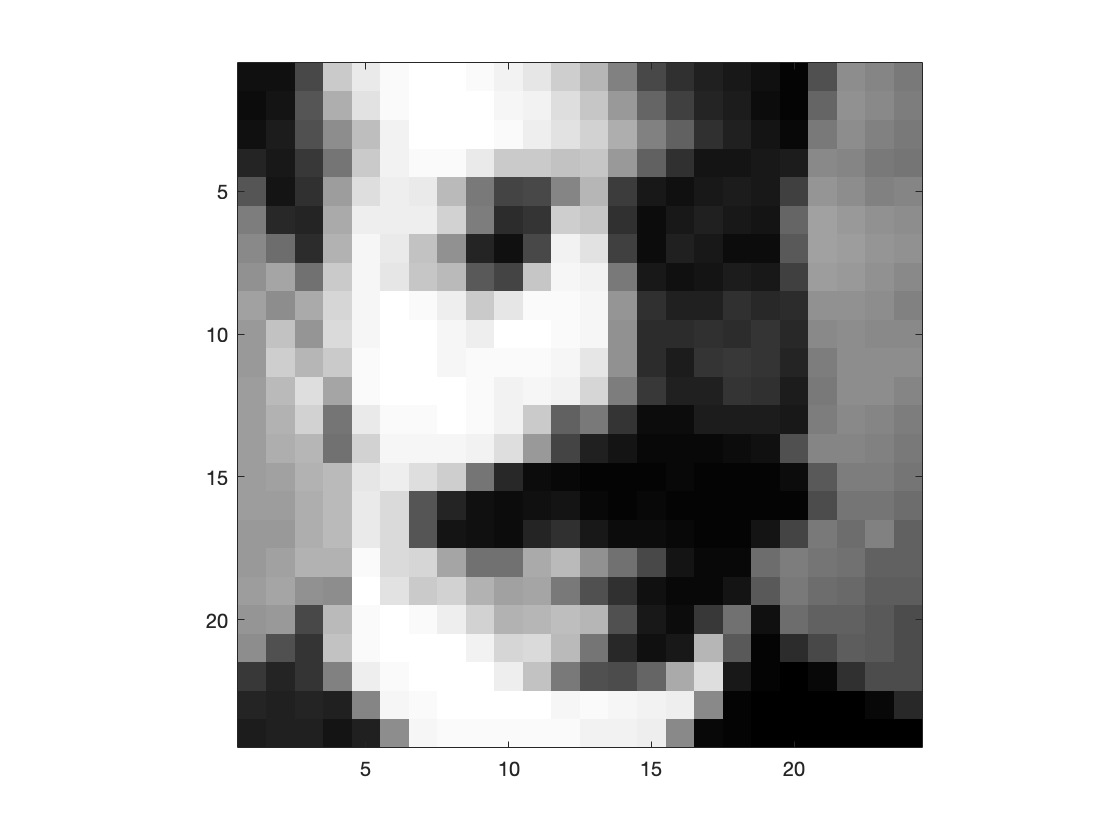

% Load the data and display a few faces 
X = load('data/faces.txt'); 
img = reshape(X(2,:),[24 24]); 
imagesc(img); axis square; colormap gray;

### Part A: Subtract the mean of the face images to make the data zero-mean

mean_X = mean(X); % Mean of data
X0 = X - mean_X; % Subtract the mean to make data zero-mean 
[U S V] = svd(X0); % Take the SVD of data 
W = U * S;

### Part B: Compute the mean square error in SVD's approxination

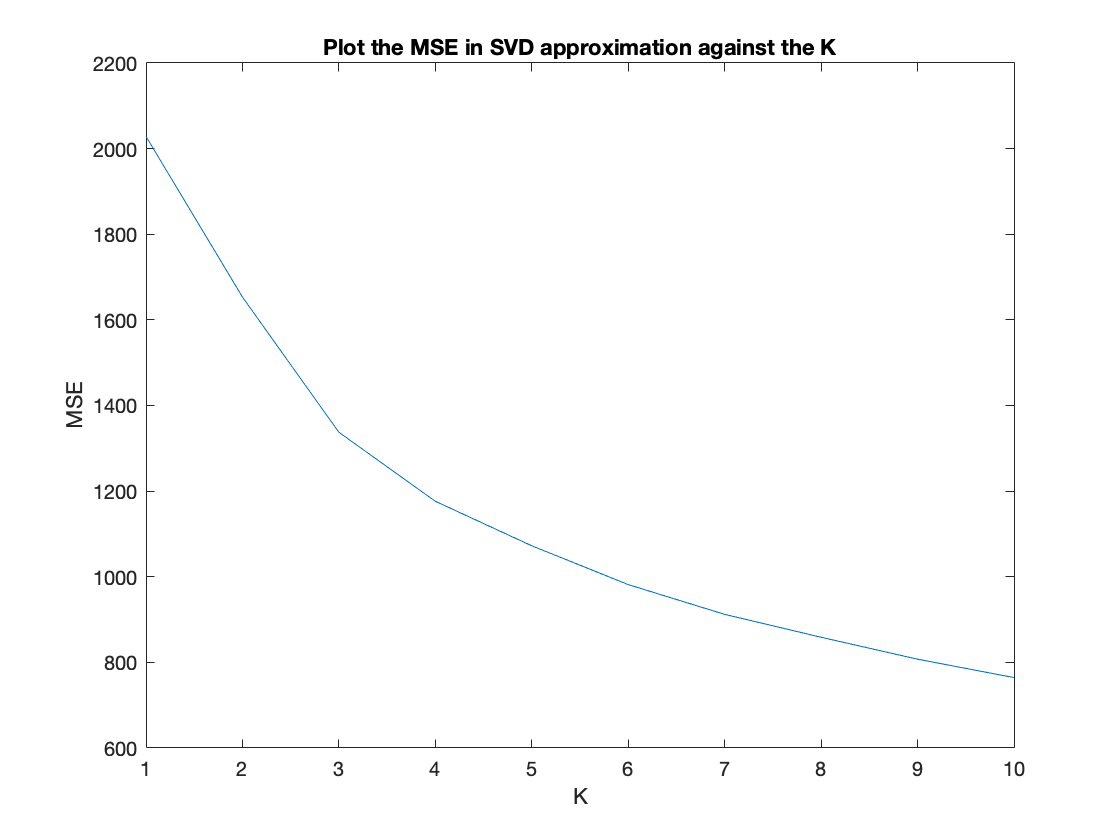

errors = zeros(1,10); % Store the MSE in SVD's approximation 
K = 1:10; % Initialize K values 
for i = 1:length(K) 
    [U_k S_k V_k] = svds(X0,K(i)); % Take the SVD of data with different K 
    X0_svd = U_k * S_k * V_k'; % Recover the data 
    mse_svd = mean(mean((X0 - X0_svd).^2)); % Compute MSE in SVD's approximation 
    errors(i) = mse_svd;     
end 
figure(1); 
plot(K,errors); 
title('Plot the MSE in SVD approximation against the K'); 
xlabel('K'); ylabel('MSE');

### Part C: Display a first few principal directions of the data

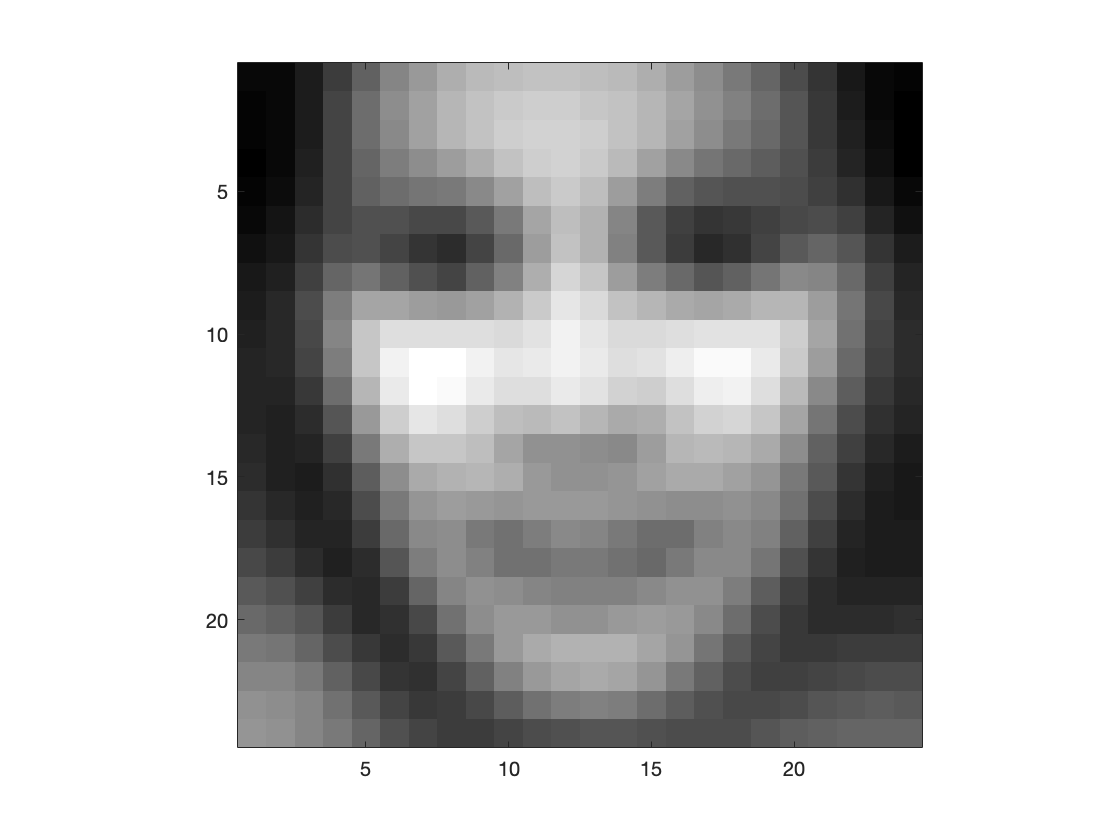

alpha = 2 * median(abs(W(:,10))); % Scale factor 
direction1 = reshape(mean_X + alpha * V(:,10)',[24,24]); % 1st principal direction
direction2 = reshape(mean_X - alpha * V(:,10)',[24,24]); % 2nd principal direction 
figure(2); 
imagesc(direction1); axis square; colormap gray; % Reshape and view as face image 

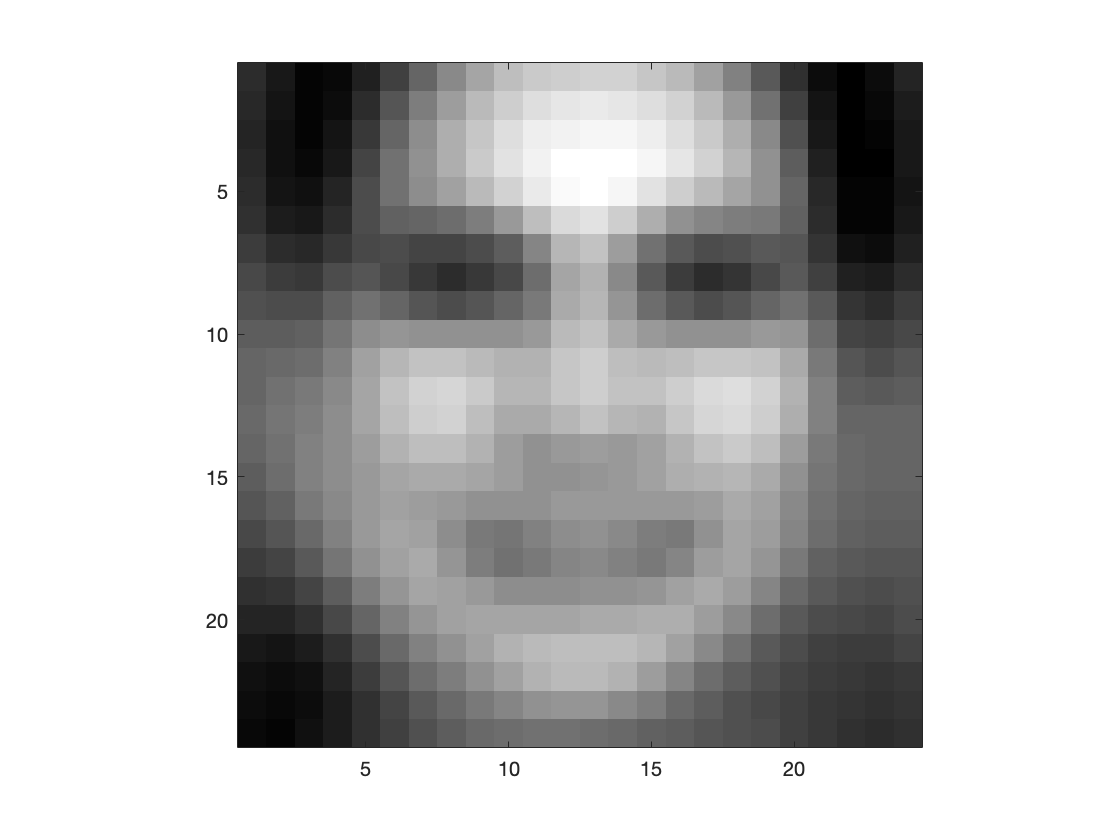

figure(3);
imagesc(direction2); axis square; colormap gray; % Reshape and view as face image 

### Part D: Latent Space methods

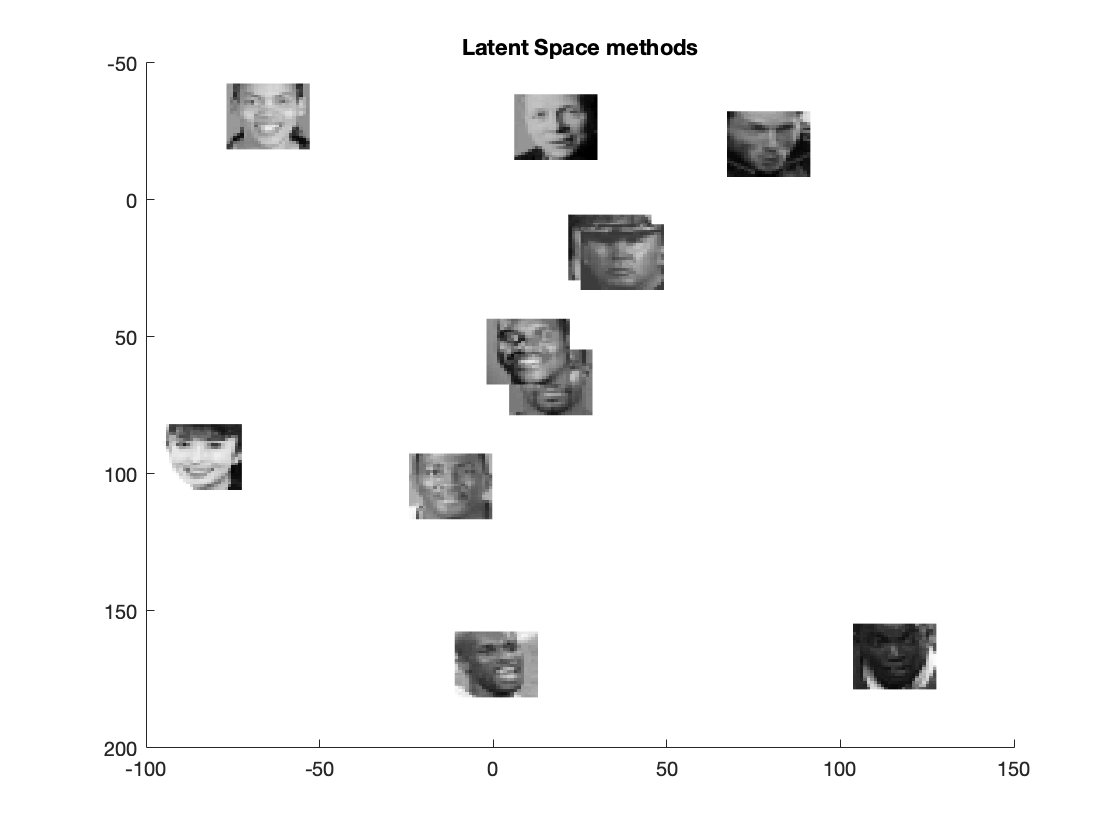

idx = 15:25; % random indices of data 
figure(4); title('Latent Space methods');  hold on; axis ij; colormap(gray); 
range = max(W(idx,1:2)) - min(W(idx,1:2)); % find range of coordinates to be plotted 
scale = [200 200]./range;                  % want 24x24 to be visible 
for i=1:length(idx)
    % scale the coordinates to display 
    imagesc(W(idx(i),1) * scale(1), W(idx(i),2) * scale(2), reshape(X(idx(i),:),24,24)); 
end

### Part E: Choose two faces and reconstruct using only K principal directions

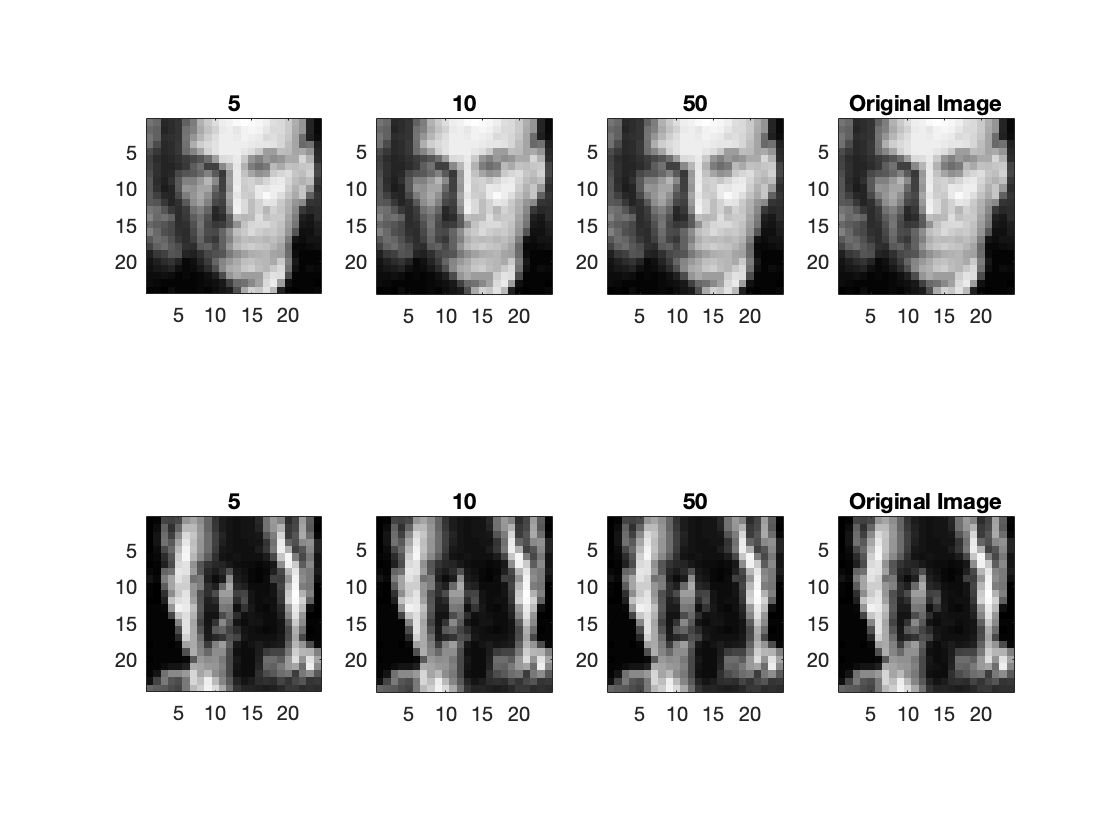

K_recover = [5,10,50]; % Use K principal directions 
indices = randperm(size(X0,1));
index1 = indices(1); index2 = indices(2); % Two random indices 
% Choose random two images 
img1 = X(index1,:); % Image 1 
img2 = X(index2,:); % Image 2
figure(5); 
title('Construct image using K principal directions'); 
for i = 1:length(K_recover)
    [U1 S1 V1] = svds(img1,K_recover(i)); % Take SVD of 1st image with different K 
    recovered_img1 = U1 * S1 * V1'; % Recover the data 
    subplot(2,4,i); 
    % Display the 1st recovered image 
    imagesc(reshape(recovered_img1,24,24)); axis square; colormap gray; 
    title([num2str(K_recover(i))]);
    [U2 S2 V2] = svds(img2,K_recover(i)); % Take SVD of 2nd image with different K  
    recovered_img2 = U2 * S2 * V2'; % Recover the data
    subplot(2,4,i+4); 
    % Display the 2nd recovered image 
    imagesc(reshape(recovered_img2,24,24)); axis square; colormap gray; 
    title([num2str(K_recover(i))]);
end 
subplot(2,4,4); imagesc(reshape(img1,24,24)); axis square; colormap gray; % Display image 1
title('Original Image'); 
subplot(2,4,8); imagesc(reshape(img2,24,24)); axis square; colormap gray; % Display image 2
title('Original Image');

## Clustering

### Part A: Load the usual Iris data with 2 features and plot

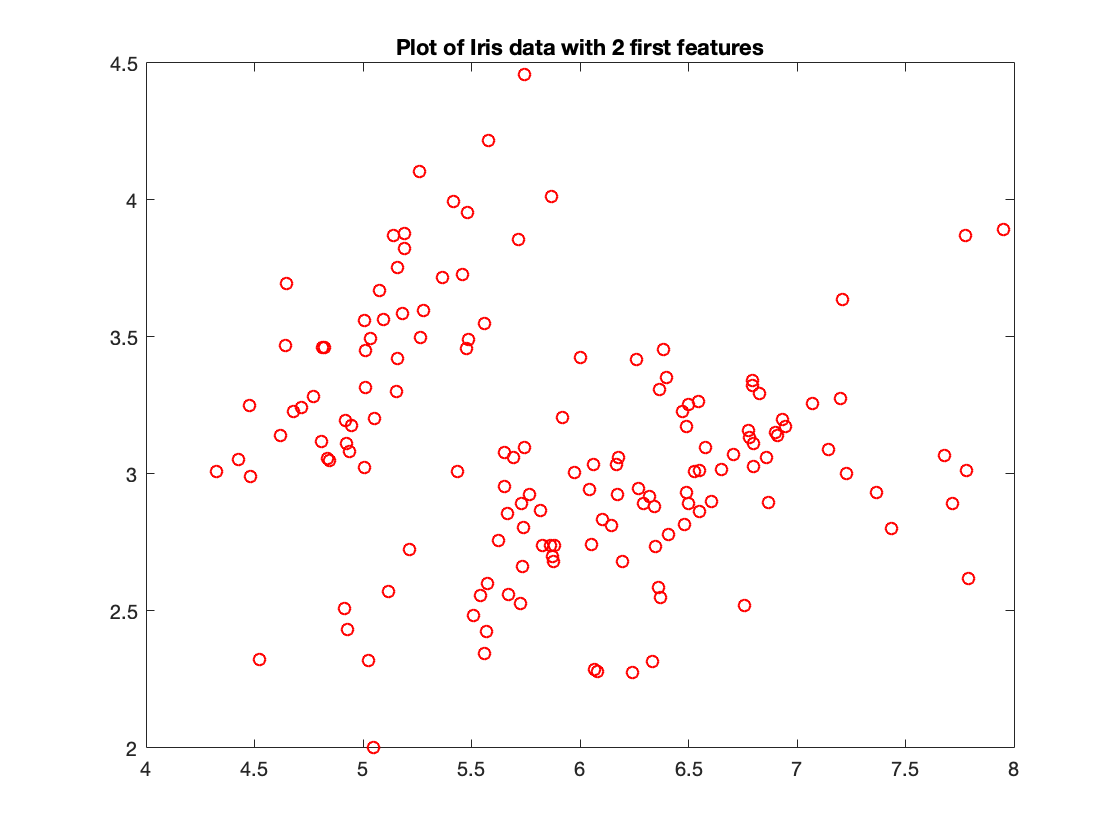

iris = load('data/iris.txt'); % Load Iris data 
X_iris = iris(:,1:2);         % Use only two first features 
figure(6); 
plot(X_iris(:,1),X_iris(:,2),'ro'); 
title('Plot of Iris data with 2 first features');

### Part B: K-Means on the data

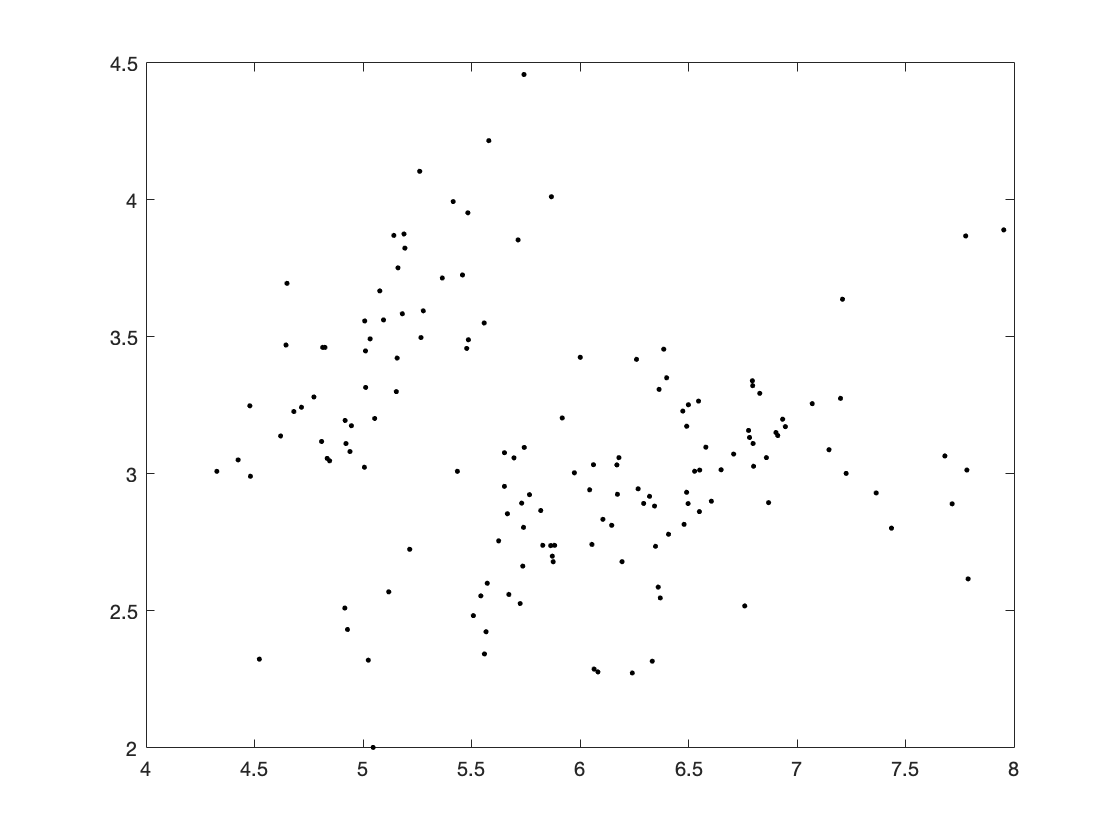

% Choose the initialization with the best score 
% Run k-means with k = 5 with farthest initialization 
figure(7);
title('k-means on the data with k = 5'); 
[z5 c5 sumd5] = kmeans(X_iris,5,'farthest',100); 
plotClassify2D([],X_iris,z5); 

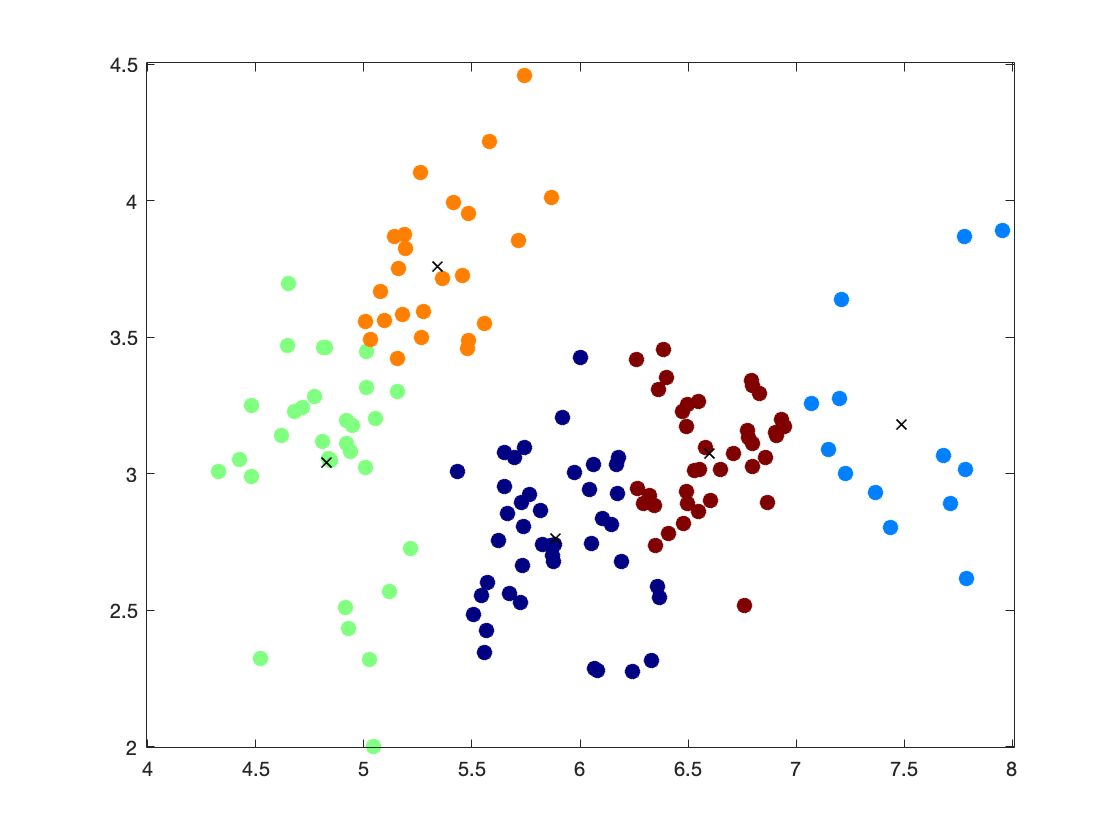

hold on 
plot(c5(:,1),c5(:,2),'kx'); 

% Run k-means with k = 20 with k++ intialization 
figure(8); 
title('k-means on the data with k = 20'); 
[z20 c20 sumd20] = kmeans(X_iris,20,'k++',100); 
plotClassify2D([],X_iris,z20); 

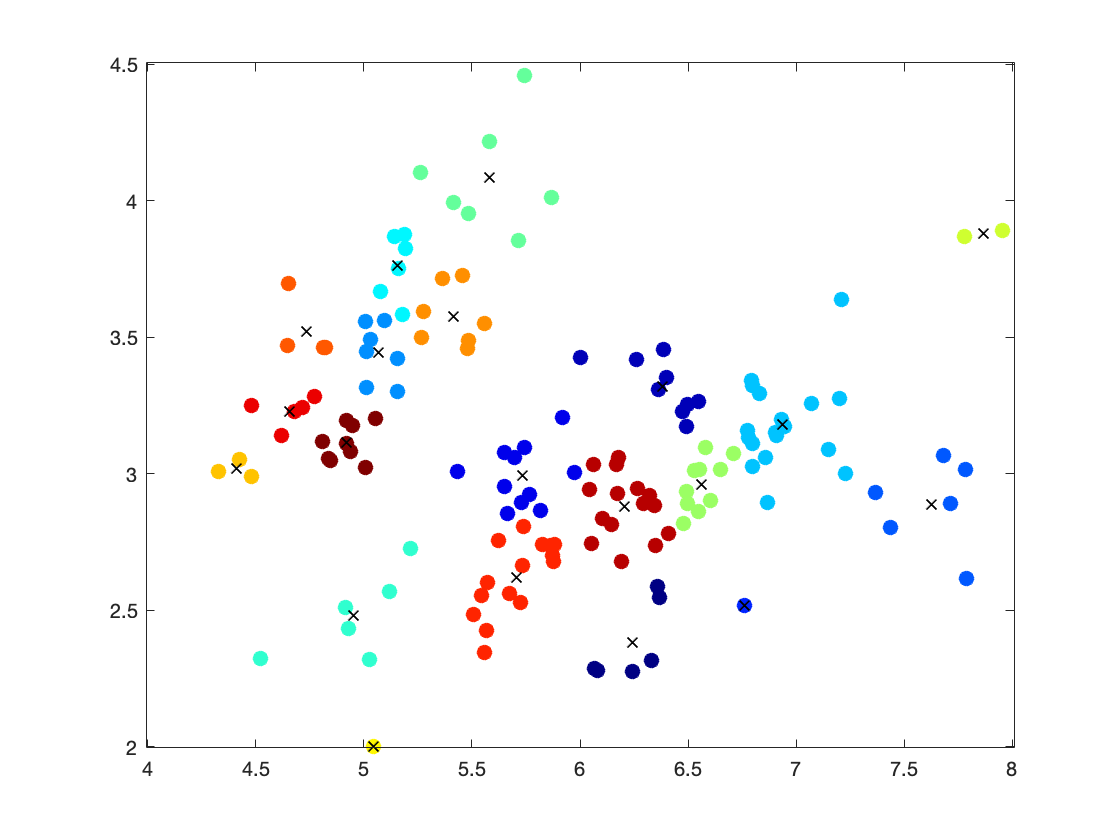

hold on 
plot(c20(:,1),c20(:,2),'kx');

### Part C: Run agglomerative clustering on the data

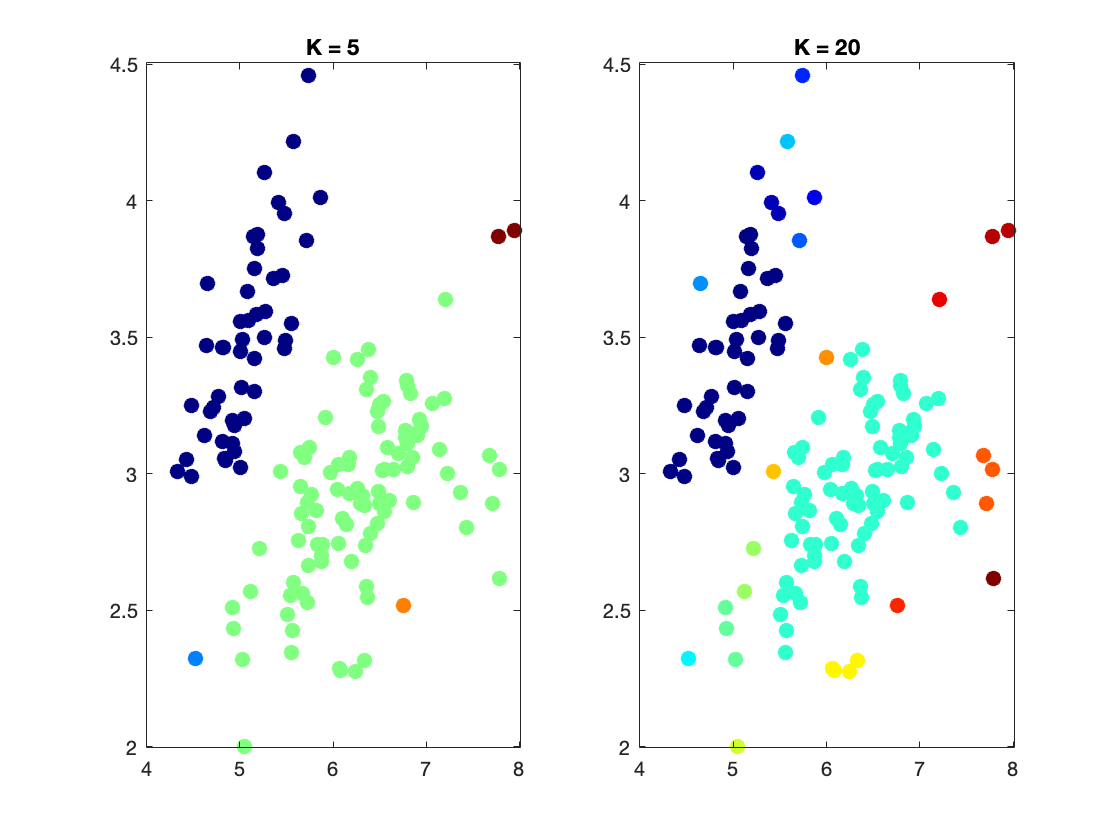

% Using single linkage on Iiris data 
[z5_min_agg join] = agglomCluster(X_iris,5,'min'); % k = 5 
[z20_min_agg join] = agglomCluster(X_iris,20,'min'); % k = 20
figure(9); 
subplot(1,2,1); 
plotClassify2D([],X_iris,z5_min_agg); 
title('K = 5'); 
subplot(1,2,2); 
plotClassify2D([],X_iris,z20_min_agg); 
title('K = 20');

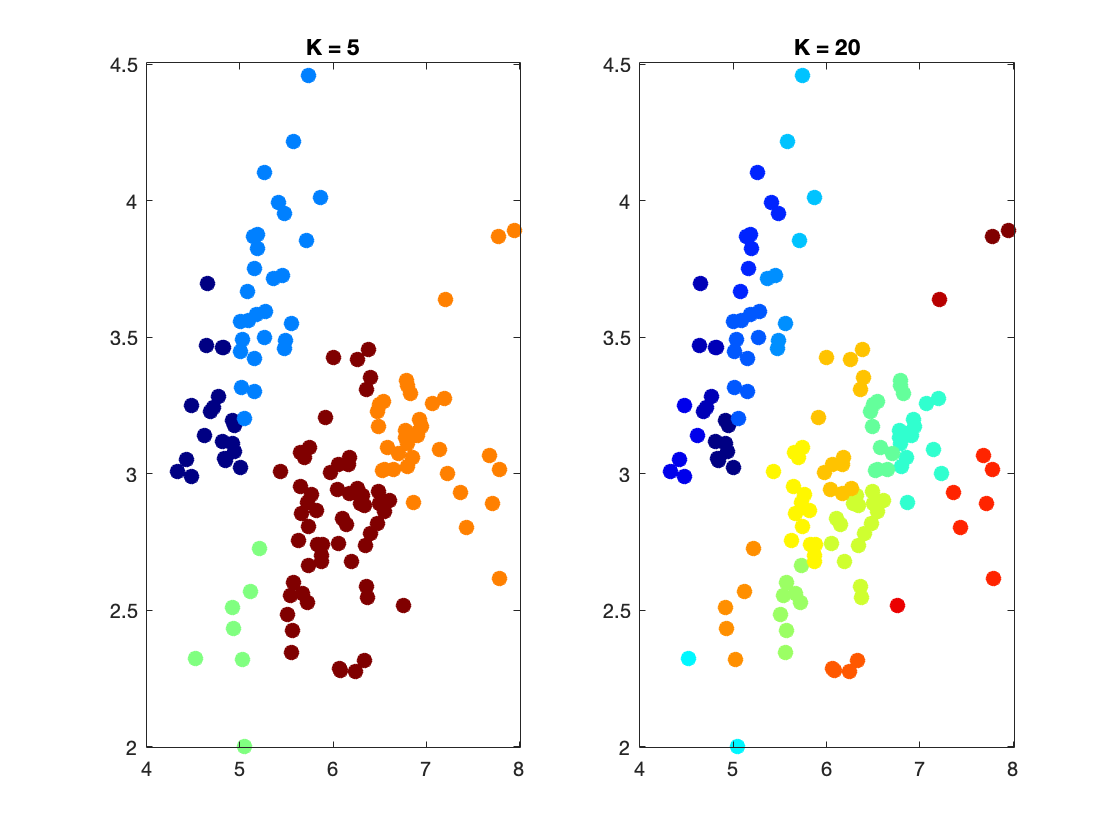

% Using complete linkage on Iris data 
[z5_max_agg join] = agglomCluster(X_iris,5,'max'); % k = 5
[z20_max_agg join] = agglomCluster(X_iris,20,'max'); % k = 20
figure(10); 
subplot(1,2,1); 
plotClassify2D([],X_iris,z5_max_agg); 
title('K = 5'); 
subplot(1,2,2); 
plotClassify2D([],X_iris,z20_max_agg); 
title('K = 20');

### Part D: Run the EM Gaussian Mixture Model 

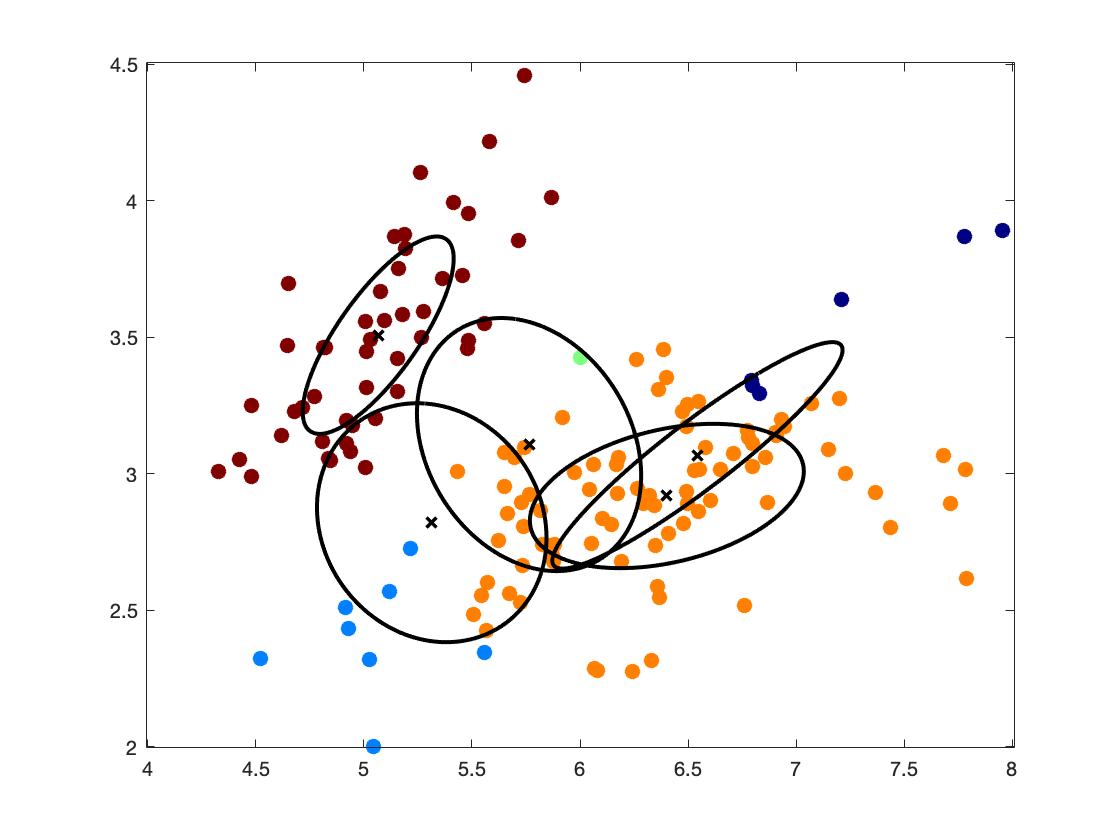

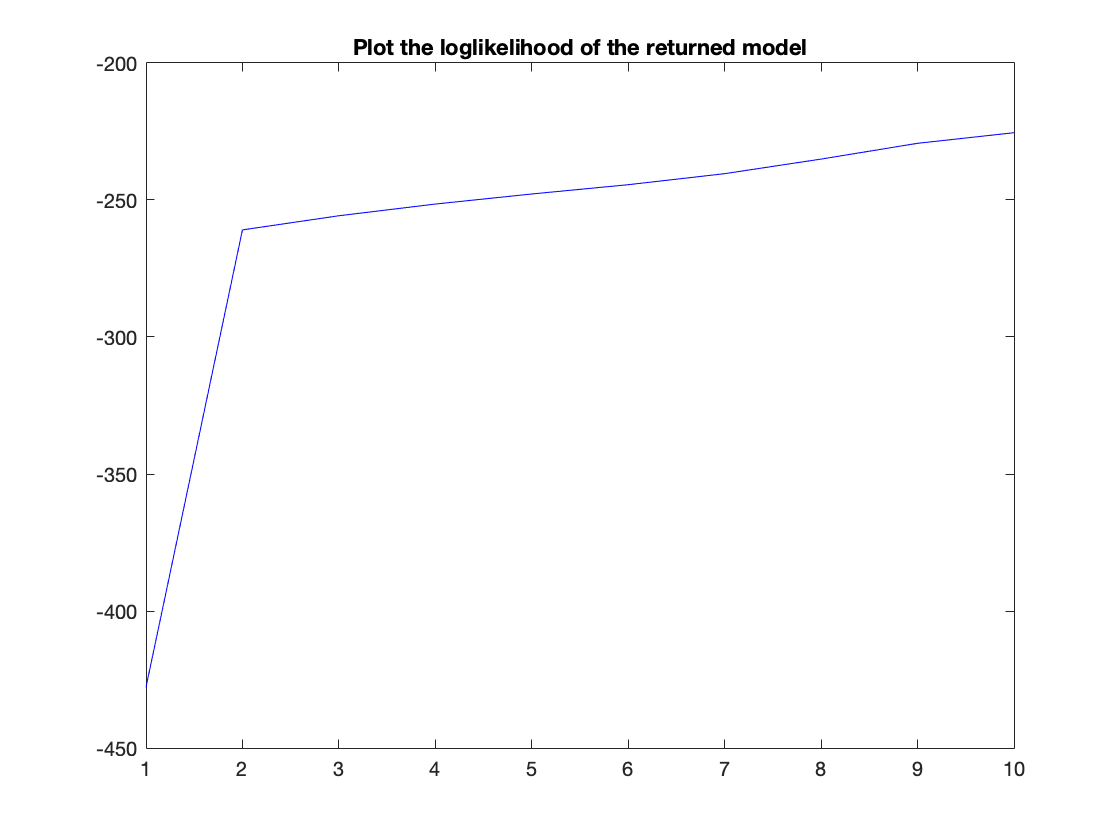

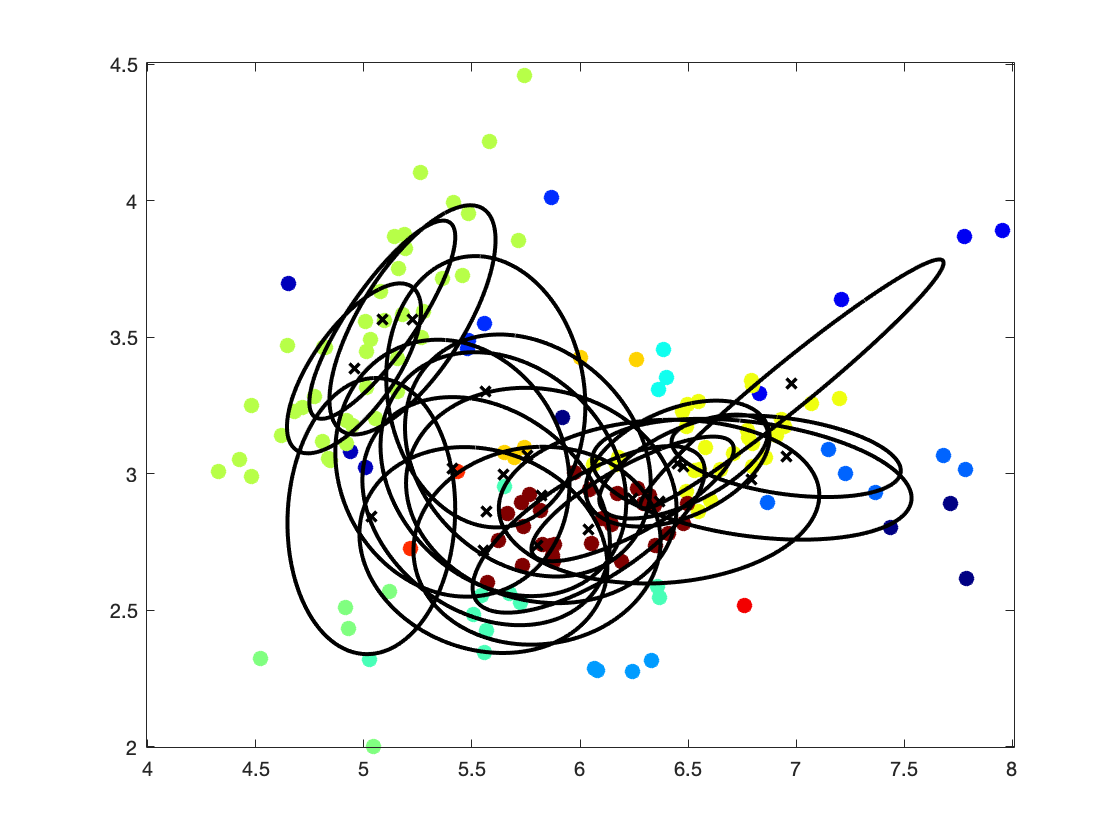

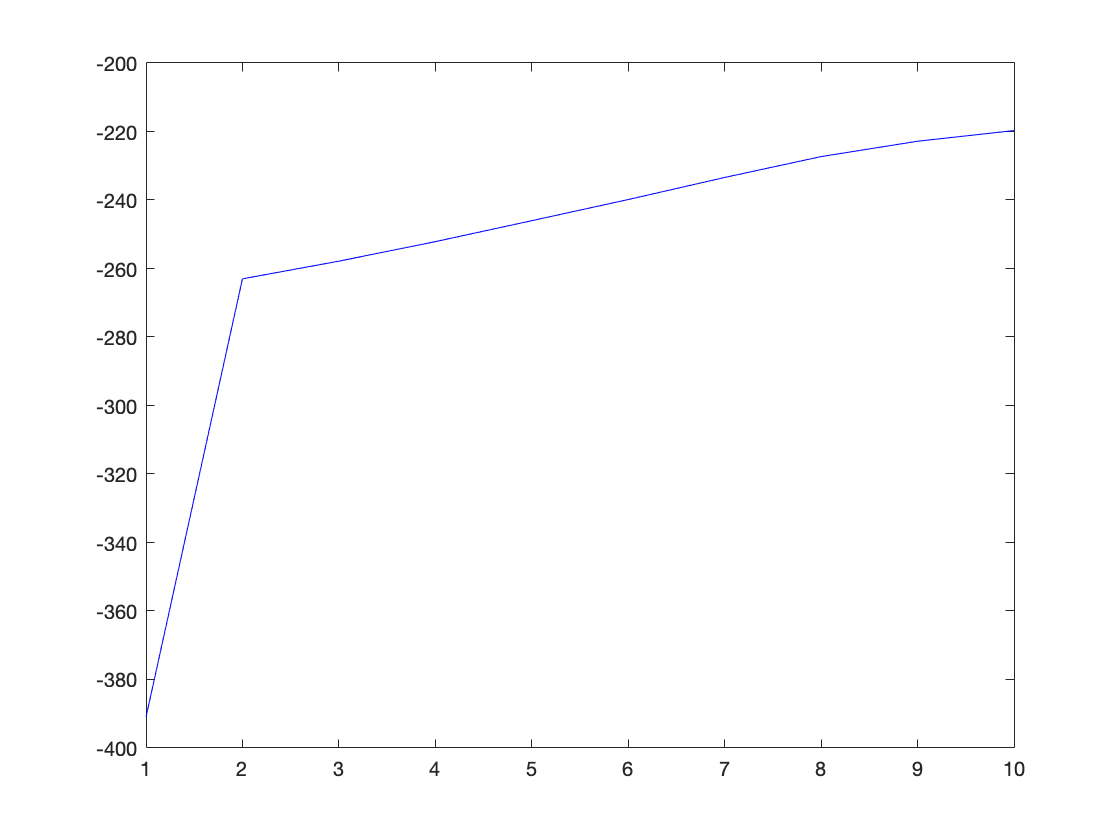

% set doPlot = true to observe the evolution of 
% mixture components's locations and shapes 
% EM Gaussian mixture model with k = 5 with farthest initialization
[z5_em,T,soft,ll] = emCluster(X_iris,5,'farthest',10); 
% EM Gaussian mixture model with k = 20 with farthest initialization 
[z20_em,T,soft,ll] = emCluster(X_iris,20,'farthest',10);